# Calcalate matched generators' features in NYCA 2019

The program is used to calculate generation features of the aggregated units in NYAM, such as max power,. min power, and max ramp rate.

## Import the data

### Import the RGGI generation data

% Import hourly generation data of generators in RGGI database in the 2019 whole year
genFileDir = "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\EPA_RGGI\2019\";
genFileName = "emission*.csv";
genDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(genDataStore);
clear genDataStore;

### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
generatorCombiner = importRefTable("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\RGGI_2_NYCA_2019.xlsx");
% Exclude generators with zero gross load in 2019
generatorCombiner = generatorCombiner(generatorCombiner.NetEnergyGWh > 1, :);

% Create arrays of key features
NYISONames = unique(generatorCombiner.NYISOName);
PTIDs = unique(generatorCombiner.PTID);
unitTypes = unique(generatorCombiner.UnitType);
fuelTypes = unique(generatorCombiner.FuelType);
Zones = unique(generatorCombiner.Zone);
numGenMatched = size(PTIDs, 1)

numGenMatched =    144


### Group summary of nameplate capacity in NYCA database

% Group summary of nameplate capacity by unit type and fuel type
unitFuelTypeSummary = groupsummary(generatorCombiner, ["UnitType", "FuelType"] , "sum", ["NamePlateRatingMW", "GrossLoadMWh"]);
total_count = sum(unitFuelTypeSummary.GroupCount);
total_cap = sum(unitFuelTypeSummary.sum_NamePlateRatingMW);
total_gen = sum(unitFuelTypeSummary.sum_GrossLoadMWh);
unitFuelTypeSummary.capPer = unitFuelTypeSummary.sum_NamePlateRatingMW/total_cap;
unitFuelTypeSummary.genPer = unitFuelTypeSummary.sum_GrossLoadMWh/total_gen;
unitFuelTypeSummary.Properties.VariableNames = ["unitType", "fuelType", "Count", "totalCapacity", "totalGeneration", "capPercent", "genPercent"]

unitFuelTypeSummary = 9×7 table
         unitType          fuelType      Count    totalCapacity    totalGeneration    capPercent    genPercent
    __________________    ___________    _____    _____________    _______________    __________    __________

    Combined Cycle        Natural Gas     59          18154           3.718e+07         0.53095        0.79631
    Combustion Turbine    Fuel Oil         8          500.9               21660         0.01465      0.0004639
    Combustion Turbine    Natural Gas     30         1247.8          1.1198e+06        0.036495       0.023983
    Jet Engine            Fuel Oil        10          564.3               35850        0.016504     0.00076782
    Jet Engine            Kerosene        25         1176.5    

unitTypeSummary = groupsummary(unitFuelTypeSummary, "unitType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
unitTypeSummary = removevars(unitTypeSummary, "GroupCount");
unitTypeSummary.Properties.VariableNames = ["unitType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

unitTypeSummary = 4×6 table
         unitType         Count    totalCapacity    capPercent    totalGeneration    genPercent
    __________________    _____    _____________    __________    _______________    __________

    Combined Cycle         59          18154          0.53095        3.718e+07         0.79631 
    Combustion Turbine     38         1748.7         0.051145       1.1414e+06        0.024447 
    Jet Engine             36         1801.3         0.052683       1.8946e+05       0.0040579 
    Steam Turbine          31          12487          0.36522       8.1796e+06         0.17519 


fuelTypeSummary = groupsummary(unitFuelTypeSummary, "fuelType", "sum", ["Count","totalCapacity", "capPercent", "totalGeneration", "genPercent"]);
fuelTypeSummary = removevars(fuelTypeSummary, "GroupCount");
fuelTypeSummary.Properties.VariableNames = ["fuelType", "Count", "totalCapacity", "capPercent", "totalGeneration", "genPercent"]

fuelTypeSummary = 4×6 table
     fuelType      Count    totalCapacity    capPercent    totalGeneration    genPercent
    ___________    _____    _____________    __________    _______________    __________

    Coal              2         810.4         0.023702       4.7214e+05         0.010112
    Fuel Oil         31        7839.8          0.22929       2.8213e+06         0.060426
    Kerosene         25        1176.5          0.03441            26821       0.00057445
    Natural Gas     106         24364          0.71259        4.337e+07          0.92889


### Combine the generation table with the reference table

% Combine the RGGI database with the NYCA database
% Join tables
genAllJoint = innerjoin(genAll,generatorCombiner,'Keys',{'FacilityName','FacilityID','UnitID'}, ...
    'LeftVariables', {'FacilityName','FacilityID', 'UnitID', 'Date', 'Hour', 'GrossLoadMW', 'HeatInputMMBtu'}, ...
    "RightVariables", {'NYISOName', 'PTID', 'Zone', 'UnitType', 'FuelType', 'Combined'});

## Generator feature calculation

### Calculate feature for each generator

% Define arrays to record NYISO generators' parameter
% We define a generator by its PTID. 147 generators.
% Different generator could have same NYISO name.
% One PTID could correspond to multiple units in the RGGI database.
maxPower = zeros(numGenMatched, 1);
minPower = zeros(numGenMatched, 1);
maxHeat = zeros(numGenMatched, 1);
minHeat = zeros(numGenMatched, 1);
maxRampUp = zeros(numGenMatched, 1);
maxRampDown = zeros(numGenMatched, 1);
HeatRateLM = zeros(numGenMatched, 2);
HeatRateQM = zeros(numGenMatched, 3);
HeatRateLMR2 = zeros(numGenMatched, 1);
HeatRateQMR2 = zeros(numGenMatched, 1);
hourlyGenFilteredTables = cell(numGenMatched, 1);

for i=1:numGenMatched
    % Subset generation table by PTID
    PTID = PTIDs(i);
    genSet = genAllJoint(genAllJoint.PTID == PTID, :);
    hourlyGen = groupsummary(genSet, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu"]);
    % Calculate ramp rate
    rampRate = hourlyGen.sum_GrossLoadMW(2:end) - hourlyGen.sum_GrossLoadMW(1:end-1);
    hourlyGen.RampRate = [0; rampRate];
    % Exclude hours with zero generation, also exclude ramp down to zero
    hourlyGenNZ = hourlyGen(hourlyGen.sum_GrossLoadMW > 0, :);
    % Calcualte max output and min output (lowest 10%)
    lowPercent = 10;
    highPercent = 100;
    [genOutIdx,genPer10,genMax,genMedian] = isoutlier(hourlyGenNZ.sum_GrossLoadMW,"percentiles", [lowPercent, highPercent]);
    [heatOutIdx,heatPer10,heatMax,heatMedian] = isoutlier(hourlyGenNZ.sum_HeatInputMMBtu,"percentiles", [lowPercent, highPercent]);
    genHeatOutIdx = genOutIdx|heatOutIdx;
    hourlyGenNZFiltered = hourlyGenNZ(~genHeatOutIdx, :);
    % Fit linear model of heat rate
    genHeatLM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW");
    HeatRateLMR2(i) = genHeatLM.Rsquared.Adjusted;
    HeatRateLM(i, :) = genHeatLM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateLMFit = genHeatLM.Fitted;
    % Fit quadratic model of heat rate
    genHeatQM = fitlm(hourlyGenNZFiltered, "sum_HeatInputMMBtu ~ 1 + sum_GrossLoadMW + sum_GrossLoadMW^2");
    HeatRateQMR2(i) = genHeatQM.Rsquared.Adjusted;
    HeatRateQM(i, :) = genHeatQM.Coefficients.Estimate.';
    hourlyGenNZFiltered.HeatRateQMFit = genHeatQM.Fitted;
    % Store the results    
    maxPower(i) = genMax;
    minPower(i) = genPer10;
    maxRampUp(i) = max(hourlyGenNZFiltered.RampRate);
    maxRampDown(i) = min(hourlyGenNZFiltered.RampRate);
    hourlyGenFilteredTables{i} = hourlyGenNZFiltered;
end

% Combine generator parameters into one summary table
maxRamp60 = (maxRampUp + abs(maxRampDown))/2;
maxRamp30 = maxRamp60/2;
maxRamp10 = maxRamp30/3;
maxRampAgc = maxRamp10/10;
paramSummary = table(PTIDs, maxPower, minPower, maxRampAgc, maxRamp10, maxRamp30, maxRamp60, HeatRateLM, HeatRateLMR2, HeatRateQM, HeatRateQMR2);
paramSummary.Properties.VariableNames(1) = "PTID";

% Remove duplicated generator names in the generator combiner (multiple RGGI generators with the same PTID)
genComNoDup = generatorCombiner(generatorCombiner.Combined == "0", ["NYISOName", "PTID", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDup = generatorCombiner(generatorCombiner.Combined == "1", ["NYISOName", "PTID", "Zone", "UnitType", "FuelType", "NamePlateRatingMW", "CapabilitySummerMW", "CapabilityWinterMW"]);
genComDupRed = unique(genComDup, 'rows');
genComRed = [genComNoDup; genComDupRed];

### Combine the calculated parameters to other NYISO generator info

% Add generator information to the generator summary table
paramSummaryJoint = outerjoin(paramSummary,genComRed,'Type','left','LeftKeys',{'PTID'},'RightKeys',{'PTID'}, ...
    "LeftVariables", {'maxPower', 'minPower', 'maxRampAgc','maxRamp10','maxRamp30', 'maxRamp60','HeatRateLM','HeatRateLMR2','HeatRateQM','HeatRateQMR2'}, ...
    "RightVariables",{'NYISOName', 'PTID', 'Zone', 'NamePlateRatingMW', 'CapabilitySummerMW', 'CapabilityWinterMW','UnitType', 'FuelType'});
paramSummaryJoint = movevars(paramSummaryJoint, ["NYISOName", 'PTID', "UnitType", "FuelType", "Zone", "NamePlateRatingMW"], "Before", "maxPower")

paramSummaryJoint = 144×18 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2                HeatRateQM                 HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________ 

## Heat rate bad fitting results analysis

### Show bad fit results

% Select R2 below 0.85 bad fit results
R2Limit = 0.8;
badFitIdx = paramSummaryJoint.HeatRateLMR2 < R2Limit;
badFitNum = nnz(badFitIdx)

badFitNum =     26


badFitTable = paramSummaryJoint(badFitIdx, :);
goodFitTable = paramSummaryJoint(~badFitIdx, :);
badFitData = hourlyGenFilteredTables(badFitIdx);

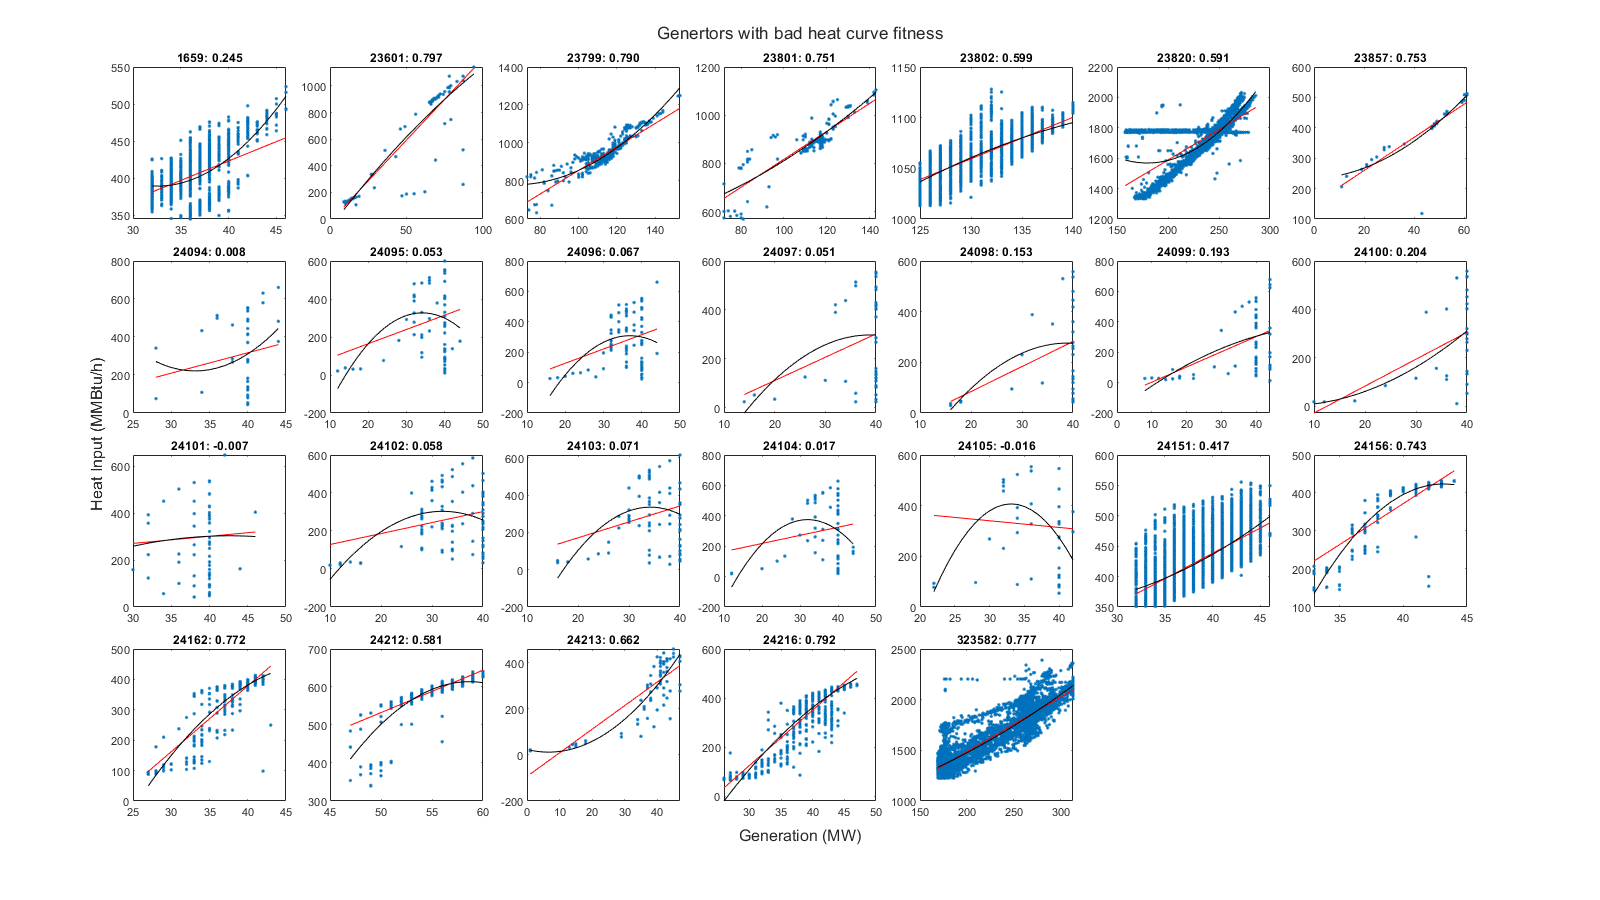

colNum = 7;
rowNum = int16(badFitNum/colNum);
t = tiledlayout(rowNum, colNum, "TileSpacing","compact");
for n=1:badFitNum
    nexttile;
    badFitPTID = badFitTable(n, :).PTID;
    badFitName = badFitTable(n, :).NYISOName;
    badFitLMR2 = badFitTable(n, :).HeatRateLMR2;
    badFitLMCoef = badFitTable(n, :).HeatRateLM;
    badFitQMCoef = badFitTable(n, :).HeatRateQM;
    badFitDataTable = badFitData{n};
%     badFitPTID = badFitPTIDs(n);
%     badFitLMR2 = badFitLMR2s(n);
%     badFitTable = badFitFilteredTables{n};
%     badFitLMCoef = badFitLMCoefs(n, :);
%     badFitQMCoefQM = badFitQMCoefs(n, :);
    scatter(badFitDataTable.sum_GrossLoadMW, badFitDataTable.sum_HeatInputMMBtu, '.');
    hold on;
    generation = min(badFitDataTable.sum_GrossLoadMW): max(badFitDataTable.sum_GrossLoadMW);
    plot(generation, badFitLMCoef(1) + badFitLMCoef(2).*generation, 'r-');
    plot(generation, badFitQMCoef(1) + badFitQMCoef(2).*generation + badFitQMCoef(3).*generation.^2, 'k-');
    hold off; box on;
    txt = sprintf("%s: %.3f", badFitPTID, badFitLMR2);
    title(txt);
end
xlabel(t, "Generation (MW)");
ylabel(t, "Heat Input (MMBtu/h)");
title(t, "Genertors with bad heat curve fitness");

set(gcf, "Position", [50, 50, 1600, 900]);

badAllIdx = (badFitTable.HeatRateLMR2) <= 0.7 & (badFitTable.HeatRateQMR2 <= 0.7);
gt100Idx = badFitTable.maxPower >= 100;
% Subset bad fit table
badFitGt100Bad = badFitTable((badAllIdx) & (gt100Idx), :) % Large CC， not sure what to do, use fitted function for now

badFitGt100Bad = 2×18 table
       NYISOName        PTID        UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60       HeatRateLM       HeatRateLMR2               HeatRateQM                HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    ________________    _____    ______________    ___________    ____    _________________    ________    ________    __________    _________    _________    _________<

badFitLt100Bad = badFitTable((badAllIdx) & (~gt100Idx), :) % Small JE and CT, treat as direct ramp units

badFitLt100Bad = 14×18 table
          NYISOName           PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2              HeatRateQM               HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    ______________________    _____    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________ 

badFitGt100LM = badFitTable((~badAllIdx) & gt100Idx, :) % Not too bad, still use fitted function

badFitGt100LM = 3×18 table
            NYISOName             PTID        UnitType        FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60       HeatRateLM       HeatRateLMR2               HeatRateQM               HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    _________________________    ______    ______________    ___________    ____    _________________    ________    ________    __________    _________    _________    

badFitLt100LM = badFitTable((~badAllIdx) & (~gt100Idx), :) % Not too bad, still use fitted function

badFitLt100LM = 7×18 table
       NYISOName        PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2               HeatRateQM                HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    ________________    _____    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________    _

### Modify parameter table due to bad fitting

% Set min power as zero
% Set max hourly ramp rate as max power (instant ramp to maximum)
badFitChanged = badFitLt100Bad;
numBadFitChanged = height(badFitChanged);
badFitUnchanged = [badFitGt100Bad; badFitGt100LM; badFitLt100LM];
badFitChanged.minPower = zeros(numBadFitChanged, 1);
badFitChanged.maxRampAgc = badFitChanged.maxPower./60;
badFitChanged.maxRamp10 = badFitChanged.maxPower./6;
badFitChanged.maxRamp30 = badFitChanged.maxPower./2;
badFitChanged.maxRamp60 = badFitChanged.maxPower;
% 1 MMBtu = 0.293 MWh, assume 25% efficiency, resulting 13.652 MMBtu/MWh
% EIA 2019 GT: 11098 Btu/kWh = 11.098 MMBtu/MWh
badFitChanged.HeatRateLM = repmat([0, 13.652], numBadFitChanged, 1);
badFitChanged.HeatRateLMR2 = zeros(numBadFitChanged, 1);
badFitChanged.HeatRateQM = zeros(numBadFitChanged, 3);
badFitChanged.HeatRateQMR2 = zeros(numBadFitChanged, 1);

## Final version of generator parameter table

paramSummaryFinal = [goodFitTable; badFitUnchanged; badFitChanged]

paramSummaryFinal = 144×18 table
        NYISOName         PTID          UnitType          FuelType      Zone    NamePlateRatingMW    maxPower    minPower    maxRampAgc    maxRamp10    maxRamp30    maxRamp60        HeatRateLM        HeatRateLMR2                HeatRateQM                 HeatRateQMR2    CapabilitySummerMW    CapabilityWinterMW
    __________________    _____    __________________    ___________    ____    _________________    ________    ________    __________    _________    _________ 

### Write parameter table of the matched generators

writetable(paramSummaryFinal, "D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\genParamMatched.csv");

## Get mpc.gen matrix output

% zoneNumArray = [1; 2; 3; 4; 5; 6; 7; 8; 9; 10; 11];
% zoneArray = categorical(["A"; "B"; "C"; "D"; "E"; "F"; "G"; "H"; "I"; "J"; "K"]);
% mpcGenM = zeros(numGenMatched, 21);
% 
% for i=1:numGenMatched
%     for j=1:size(zoneArray, 1)
%         if zoneArray(j) == paramSummaryFinal.Zone(i)        
%             busID = zoneArray(j);
%         end
%     end
%     mpcGenM(i, 1) = busID; % bus ID
% end
% mpcGenM(:, 2) = zeros(size(NYISONames)); % Pg
% mpcGenM(:, 3) = zeros(size(NYISONames)); % Qg
% mpcGenM(:, 4) = 9999*ones(size(NYISONames)); % Qmax
% mpcGenM(:, 5) = -9999*ones(size(NYISONames)); % Qmin
% mpcGenM(:, 6) = 1.00*ones(size(NYISONames)); % Vg
% mpcGenM(:, 7) = 100*ones(size(NYISONames)); % mBase
% mpcGenM(:, 8) = 1*ones(size(NYISONames)); % Status
% mpcGenM(:, 9) = paramSummaryFinal.maxPower; % Pmax
% mpcGenM(:, 10) = paramSummaryFinal.minPower; % Pmin
% % 11-16 all zeros: Pc1, Pc2, Qc1min, Qc1max, Qc2min, Qc2max
% mpcGenM(:, 17) = paramSummaryFinal.maxRampAgc; % ramp_agc
% mpcGenM(:, 18) = paramSummaryFinal.maxRamp10; % ramp_10
% mpcGenM(:, 19) = paramSummaryFinal.maxRamp30; % ramp_30
% % 20-21 all zeros: ramp_q, apf
% mpcGenM

## Calcualte generation cost

% % Need to update the prices
% coalPrice = 3.663;
% NGPrice = 4.922;
% FOPrice = 18.664;
% KSPrice = 18.664;
% costLM = zeros(size(NYISONames, 1), 2);
% for i=1:size(NYISONames)
%     fuel = paramSummaryFinal(i, :).FuelType;
%     heatRateLM = paramSummaryFinal(i, :).HeatRateLM;
%     if fuel == "Coal"
%         costLM(i, :) = coalPrice * heatRateLM;
%     elseif fuel == "Natural Gas"
%         costLM(i, :) = NGPrice * heatRateLM;
%     elseif fuel == "Fuel Oil"
%         costLM(i, :) = FOPrice * heatRateLM;
%     elseif fuel == "Kerosene"
%         costLM(i, :) = KSPrice * heatRateLM;
%     else
%         disp("Error!");
%     end
% end
% paramSummaryFinal.CostLM = costLM;
% paramSummaryFinal

## Get mpc.gencost matrix output

% mpcGenCostM = zeros(size(NYISONames, 1), 6);
% mpcGenCostM(:, 1) = 2*ones(size(NYISONames)); % Cost Model
% mpcGenCostM(:, 2) = zeros(size(NYISONames)); % Startup cost
% mpcGenCostM(:, 3) = zeros(size(NYISONames)); % Shutdown cost
% mpcGenCostM(:, 4) = 2*ones(size(NYISONames)); % number of parameters: linear=2
% mpcGenCostM(:, 5:6) = paramSummaryFinal.CostLM;
% mpcGenCostM

## Write gen matrix to file

% save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MGen.mat", "mpcGenM", "-mat");
% save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MGenCost.mat", "mpcGenCostM", "-mat");
% save("D:\EERL\NY-Simple-Net\NY-Simple-Net-main\Data\MParamSummary.mat", "paramSummaryFinal", "-mat");